# Wavelets used for Continuous Waveket Transform (CWT)

waveinfo('mexh')  % wavelets information

 Information on Mexican Hat wavelet.
 
    Mexican Hat Wavelet
 
    Definition: second derivative of the Gaussian 
    probability density function
 
    mexh(x) = c * exp(-x^2/2) * (1-x^2)
    where c = 2/(sqrt(3)*pi^{1/4}) 
 
    Family                  Mexican hat
    Short name              mexh
 
    Orthogonal              no
    Biorthogonal            no
    Compact support         no
    DWT                     no
    CWT                     possible
 
    Support width           infinite
    Effective support       [-5 5]
    Symmetry                yes
 
    Reference: I. Daubechies, 
    Ten lectures on wavelets, 
    CBMS, SIAM, 61, 1994, 75.



waveinfo('morl') 

 Information on Morlet wavelet.
 
    Morlet Wavelet
 
    Definition: 
    morl(x) = exp(-x^2/2) * cos(5x)
 
    Family                  Morlet
    Short name              morl
 
    Orthogonal              no
    Biorthogonal            no
    Compact support         no
    DWT                     no
    CWT                     possible
 
    Support width           infinite
    Effective support       [-4 4]
    Symmetry                yes
 
    Reference: I. Daubechies, 
    Ten lectures on wavelets, 
    CBMS, SIAM, 61, 1994, 76.



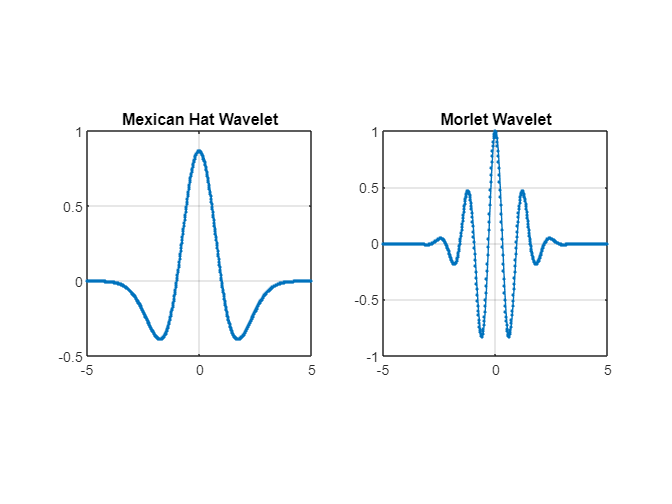


[psi1 , xval1] = wavefun ('mexh',10); % Mexican Hat wavelet
[psi2 , xval2] = wavefun ('morl',10); % Morlet wavelet

figure 
subplot (1 ,2 ,1)
plot (xval1 , psi1, '.-')
title("Mexican Hat Wavelet")
grid on, axis square, xlim([-5 5])
subplot (1 ,2 ,2) 
plot (xval2 , psi2, '.-' )
title("Morlet Wavelet")
grid on, axis square, xlim([-5 5])

## CWT and scalogram

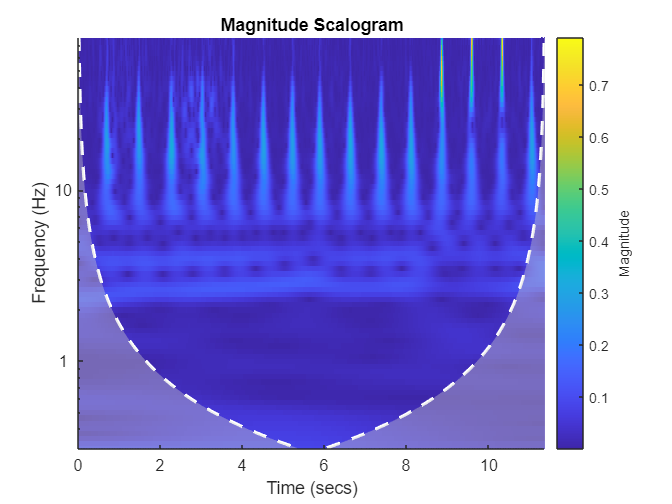

load wecg.mat wecg
ydata = wecg;

Fs = 180; 
cwt(ydata, 'morse', Fs)

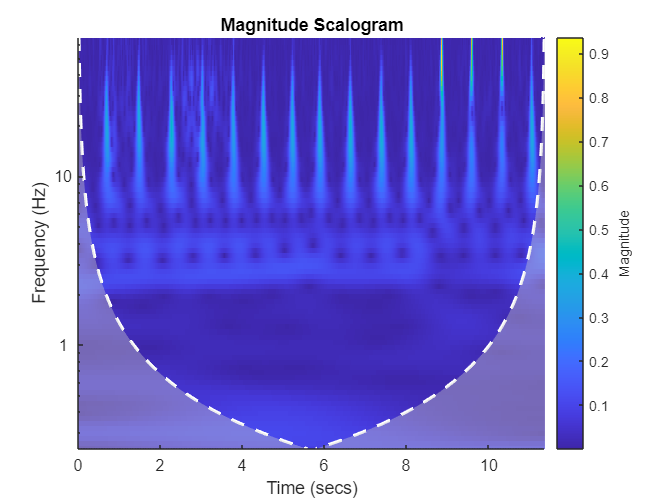

cwt(ydata, 'amor', Fs)

## Customized scalogram

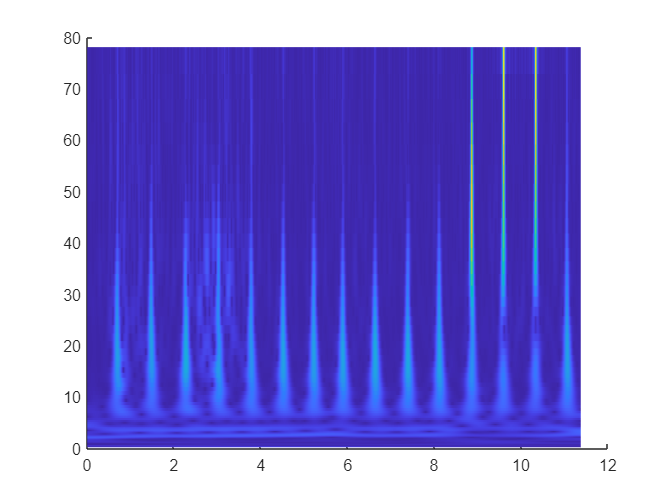

[cfs , frq] = cwt(ydata, 'morse', Fs); % compute CWT
figure
t = (0:numel(ydata)-1)/Fs;  % 1 x Nsamples
surface (t,frq , abs(cfs))
shading flat